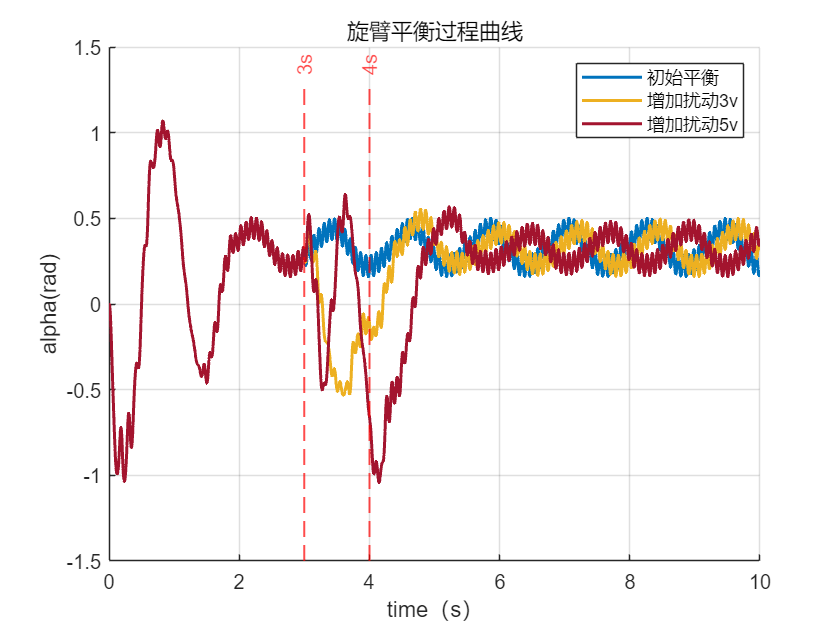

clc
% 生成蓝色渐变（5条线）
colors = [
    0.00 0.45 0.74;  % 蓝
    0.93 0.69 0.13;  % 黄
    0.64 0.08 0.18;  % 红
    
    
    0.85 0.33 0.10;  % 橙
    0.49 0.18 0.56;  % 紫
    0.47 0.67 0.19;  % 绿
    0.30 0.75 0.93;  % 浅蓝
    
];
set(gca, 'ColorOrder', colors, 'NextPlot', 'replacechildren'); % 全局配色
plot(tout,alpha(:,1),'LineWidth', 1.5);
hold on;
plot(tout,alpha(:,2),'LineWidth', 1.5);
hold on;
plot(tout,alpha(:,3),'LineWidth', 1.5);


ax = gca; % 获取当前坐标区句柄
ax.XLabel.String = 'time（s）';  % X轴标签
ax.YLabel.String = 'alpha(rad)'; % Y轴标签
ax.Title.String = '旋臂平衡过程曲线'; % 标题

% 在 3s 和 4s 处添加竖直虚线
xline(3, '--r', '3s', 'LineWidth', 1, 'LabelHorizontalAlignment', 'center'); % 红色虚线，标注"3s"
xline(4, '--r', '4s', 'LineWidth', 1, 'LabelHorizontalAlignment', 'center'); % 红色虚线，标注"4s"
grid on; % 可选：显示网格

legend('初始平衡','增加扰动3v', "增加扰动5v"); % 添加图例

% 生成蓝色渐变（5条线）
colors = [
    0.00 0.45 0.74;  % 蓝
    0.93 0.69 0.13;  % 黄
    0.64 0.08 0.18;  % 红
    
    
    0.85 0.33 0.10;  % 橙
    0.49 0.18 0.56;  % 紫
    0.47 0.67 0.19;  % 绿
    0.30 0.75 0.93;  % 浅蓝
    
];
set(gca, 'ColorOrder', colors, 'NextPlot', 'replacechildren'); % 全局配色

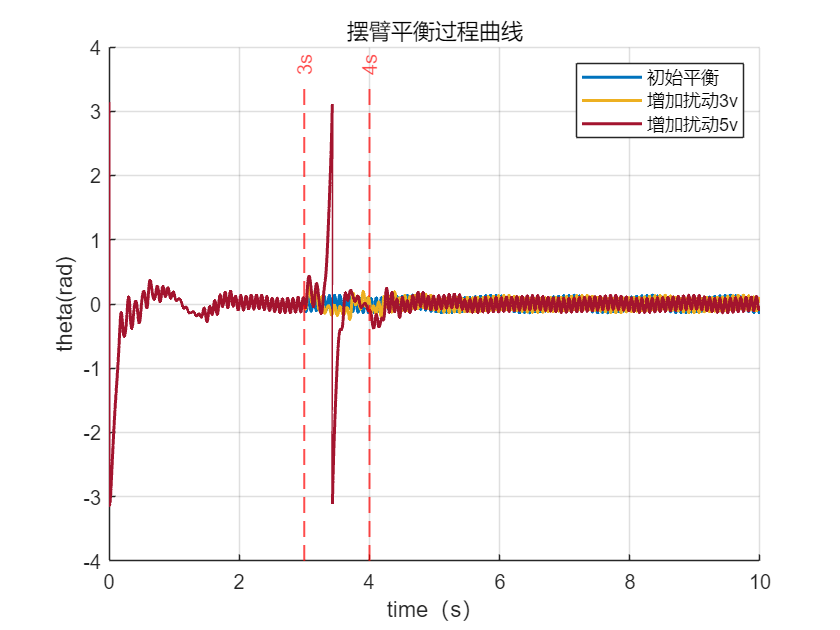

plot(tout,theta(:,1),'LineWidth', 1.5);
hold on;
plot(tout,theta(:,2),'LineWidth', 1.5);
hold on;
plot(tout,theta(:,3),'LineWidth', 1.5);


ax = gca; % 获取当前坐标区句柄
ax.XLabel.String = 'time（s）';  % X轴标签
ax.YLabel.String = 'theta(rad)'; % Y轴标签
ax.Title.String = '摆臂平衡过程曲线'; % 标题

% 在 3s 和 4s 处添加竖直虚线
xline(3, '--r', '3s', 'LineWidth', 1, 'LabelHorizontalAlignment', 'center'); % 红色虚线，标注"3s"
xline(4, '--r', '4s', 'LineWidth', 1, 'LabelHorizontalAlignment', 'center'); % 红色虚线，标注"4s"
grid on; % 可选：显示网格

legend('初始平衡','增加扰动3v', "增加扰动5v"); % 添加图例